# Decision Trees

## What are decision trees? 

A **decision tree** algorithm constructs a set of decisions based on training data. Its structure is comprised of decision nodes connected by edges. Data points are processed by moving through a decision tree, which uses binary/ternary rules to calculate a target value. 

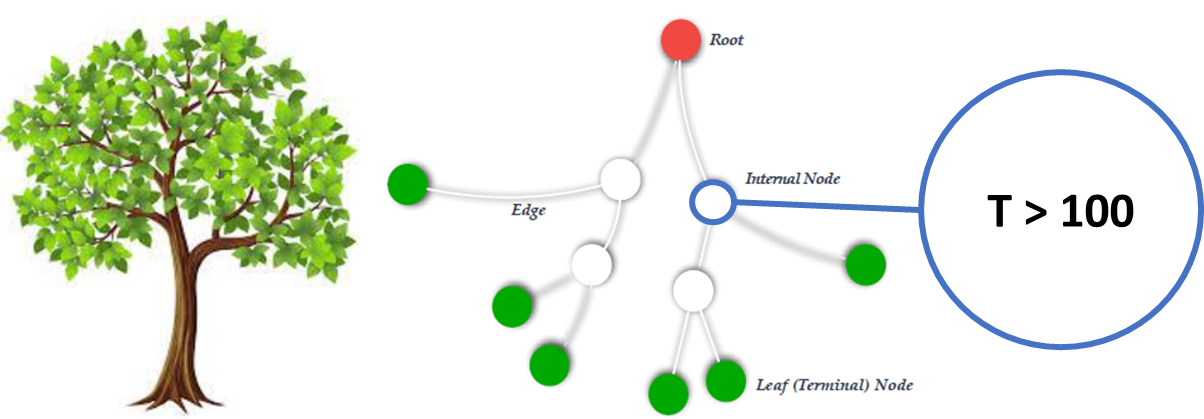

Advantages:

- Easy to visualize and interpret

- Structure is easily explainable

- Can be used for both classification and regression purposes

- Can work with missing data

- Naturally non-linear

## Decision trees for classification - a toy example

To explain how decision trees can be applied for a classification problem, we will use data pertaining to weather conditions and how this influences the likelihood that John will play tennis: 

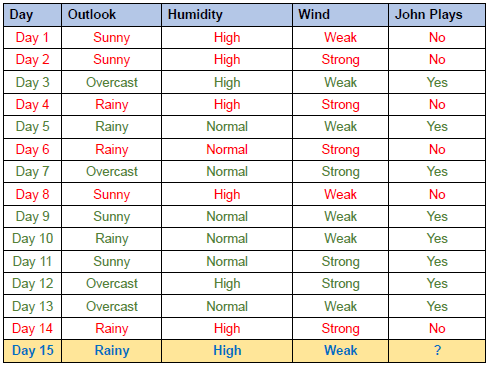

Based on data that has been recorded, we can derive a set of rules that gradually distinguish between classes (whether John plays tennis or not): 

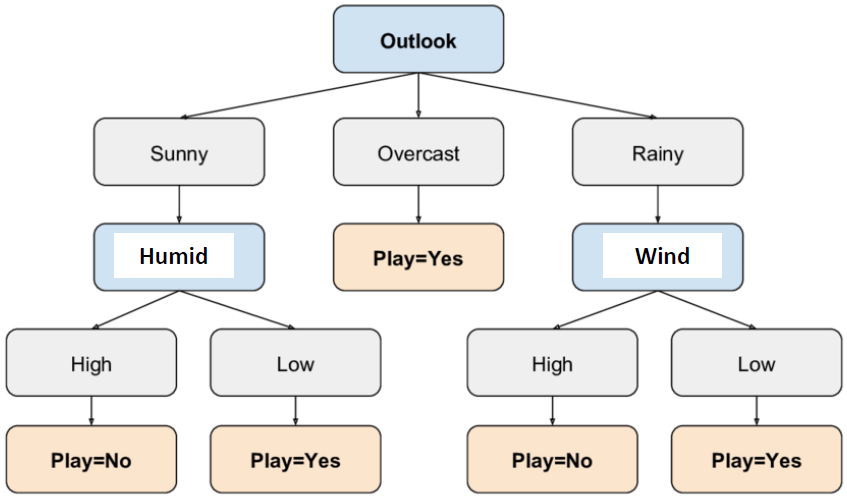

### How do we choose the best attributes? 

In principle, the best attributes are those that optimally separate the training examples as much as possible. There are multiple ways to quantitatively define this separation, but we'll specifically discuss entropy within this lesson.

**Entropy** is defined as lack of order or predictability. When applied with decision trees, we aim to identify the set of attributes that minimize entropy when predicting outcomes. Mathematically, we define entropy as: 


$$\textrm{Entropy}=-\sum_i p\left(x_i \right)\log_2 p\left(x_i \right)$$


where $p\left(x_i \right)$ denotes the probability for the outcome to be class $i$. By minimizing entropy, we maximize the separation between different classes. We can alternative think about this concept using a probability distribution: 

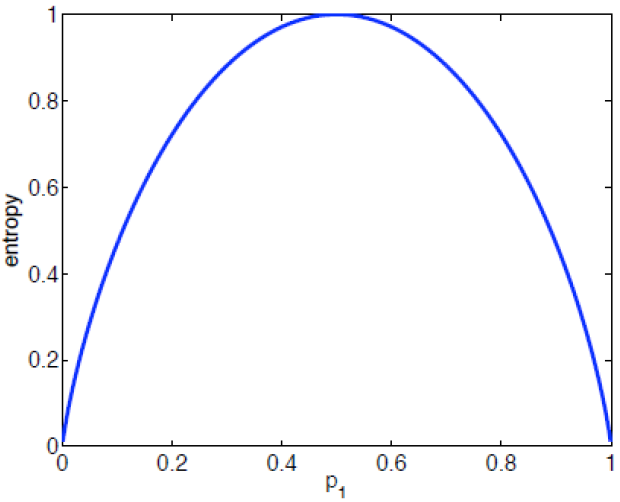

Using this perspective, greater deviation from uniformity in the probability distribution between classes results in lower entropy. 

### Hyperparameter tuning for decision trees

Sometimes, minimizing entropy (or another optimization function) does not yield the best decision tree model. For instance, a tree with each node corresponding to each data point has an entropy of 0 - but this model will perform poorly when applied with new data. To avoid this situation, we can customize **hyperparameters** that define tree size and complexity. Specific parameters include: 

- The depth of the tree: deep trees are more complex and may overfit

- The minimum number of samples in a node: each node should have at least 2 samples before it can split

- The maximum number of leaf nodes: too many nodes may lead to a model where each terminal node corresponds to a single data point

## In-class example: predicting diabetes using the Framingham dataset

To learn how to develop decision trees for classification in MATLAB, we'll use the Framingham dataset to predict whether a patient is diabetic or not. First, we'll load the data and define our inputs (X) and output (Y). We'll also subset them into training and testing sets: 

% Load the dataset
fram = readtable('frmgham2.xls');

% Extract all features except diabetes (column 10)
X = fram(:, [1:9, 11:14]);

% Define output variable (diabetes)
Y = fram.DIABETES;

% Subset data into training/testing sets via 30% holdout
idx = crossvalind('HoldOut', Y, 0.3); 
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

We'll now create a classification tree using the `fitctree` function and display its structure using the `view` function: 

% Create classification tree
Decision_Tree = fitctree(Xtrain, Ytrain) 

Decision_Tree =   ClassificationTree
           PredictorNames: {'RANDID'  'SEX'  'TOTCHOL'  'AGE'  'SYSBP'  'DIABP'  'CURSMOKE'  'CIGPDAY'  'BMI'  'BPMEDS'  'HEARTRTE'  'GLUCOSE'  'educ'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 8139


  Properties, Methods


% View tree structure as set of rules
view(Decision_Tree)

Decision tree for classification
  1  if GLUCOSE<143.5 then node 2 elseif GLUCOSE>=143.5 then node 3 else 0
  2  if GLUCOSE<113.5 then node 4 elseif GLUCOSE>=113.5 then node 5 else 0
  3  if GLUCOSE<182.5 then node 6 elseif GLUCOSE>=182.5 then node 7 else 1
  4  if TOTCHOL<441 then node 8 elseif TOTCHOL>=441 then node 9 else 0
  5  if BMI<27.05 then node 10 elseif BMI>=27.05 then node 11 else 0
  6  if DIABP<67 then node 12 elseif DIABP>=67 then node 13 else 1
  7  class = 1
  8  if educ<1.5 then node 14 elseif educ>=1.5 then node 15 else 0
  9  if BMI<27.77 then node 16 elseif BMI>=27.77 then node 17 else 0
 10  if RANDID<4.50897e+06 then node 18 elseif RANDID>=4.50897e+06 then node 19 else 0
 11  if RANDID<8.52235e+06 then node 20 elseif RANDID>=8.52235e+06 then node 21 else 0
 12  class = 0
 13  if RANDID<7.92665e+06 then node 22 elseif RANDID>=7.92665e+06 then node 23 else 1
 14  if BPMEDS<0.5 then node 24 elseif BPMEDS>=0.5 then node 25 else 0
 15  if BPMEDS<0.5 then node 26 elsei

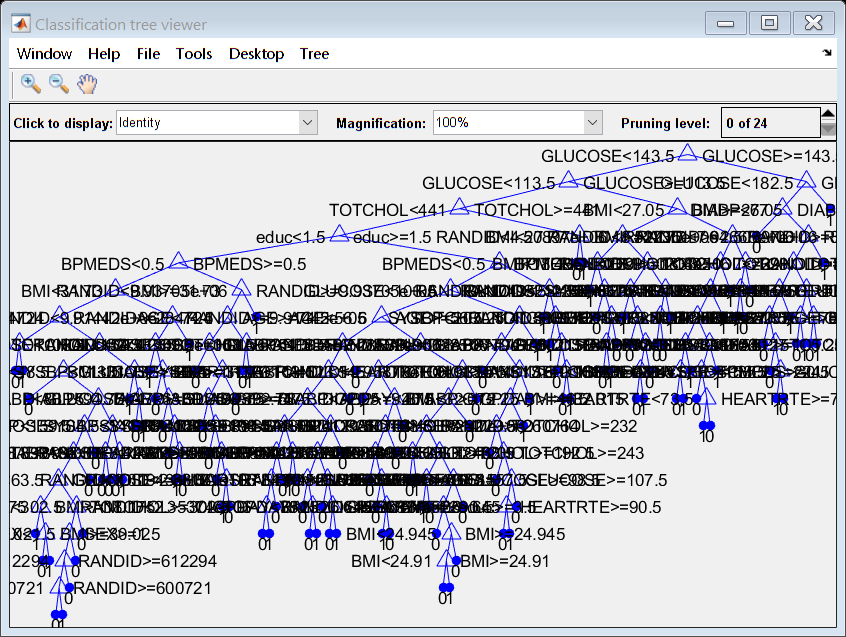

% View tree structure graphically
view(Decision_Tree, 'mode', 'graph')

### Assessing and improving tree quality

The **resubstitution error** is the difference between predicted vs. actual outcomes of the input training data. If the resubstitution error is high, you cannot expect the predictions of the tree to be good. However, having low resubstitution error does not guarantee good predictions for new data. The resubstitution error is often an overly optimistic estimate of the predictive error on new data.

% Examine the resubsitution error
resuberror = resubLoss(Decision_Tree); 
fprintf('The resubstitution classification error is %4.2f \n', resuberror)

The resubstitution classification error is 0.02 


We can also assess our model quality via **cross-validation** (CV). In MATLAB, the `cvloss` function performs a 10-fold CV (default) and reports the average test set error: 

% Perform 10-fold cross-validation
cverror = cvloss(Decision_Tree); 
fprintf('The 10-fold cross-validation error is %4.2f \n', cverror)

The 10-fold cross-validation error is 0.05 


Rather than developing a single model and assessing its quality, we can use tree quality assessment techniques to identify additional tweaks we can implement to build the best model. For example, we can adjust the depth of our tree (via **pruning**) based on how the CV loss error changes with tree depth: 

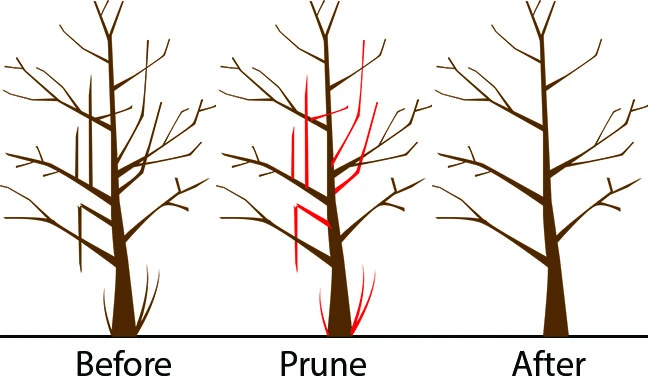

We can do this in MATLAB using the `cvloss` function and specifying a value for the `subtrees` parameter: 

% Assess how CV error changes with pruning the first 10 layers
cverror_prune10 = cvloss(Decision_Tree, 'Subtrees', 0:10); 
table([0:10]', cverror_prune10, 'VariableNames', {'Prune Level', 'CV Error'})

ans = 11×2 table
    Prune Level    CV Error
    ___________    ________

         0         0.048409
         1         0.048409
         2         0.047917
         3         0.047303
         4         0.047303
         5         0.047303
         6         0.047057
         7         0.046935
         8         0.046812
         9         0.045706
        10         0.044723


% Assess CV error for all pruning levels
cverror_pruneAll = cvloss(Decision_Tree, 'Subtrees', 'all'); 
table([0:numel(cverror_pruneAll)-1]', cverror_pruneAll, 'VariableNames', {'Prune Level', 'CV Error'})

ans = 25×2 table
    Prune Level    CV Error
    ___________    ________

         0         0.049515
         1         0.049515
         2           0.0489
         3         0.048286
         4         0.048286
         5         0.048286
         6          0.04804
         7         0.047917
         8         0.047917
         9         0.047426
        10         0.045583
        11         0.044477
        12         0.043249
        13         0.042266
        14         0.041897
        15         0.040668


% Determine the best pruning level
[~, ~, ~, Best_prune_level] = cvloss(Decision_Tree, 'Subtrees', 'all')

Best_prune_level = 23

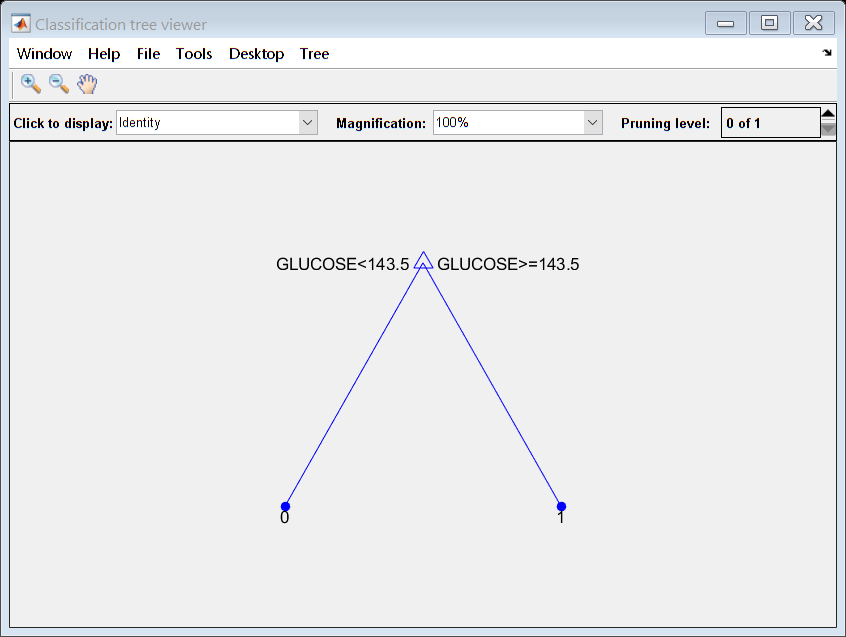

% Prune tree based on optimal level
pruned_tree = prune(Decision_Tree, 'Level', Best_prune_level); 
view(pruned_tree, 'Mode', 'Graph')

### **Hyperparameter tuning: controlling tree "leafiness"**

When you grow a decision tree, consider its simplicity and predictive power. A deep tree with many leaves is usually highly accurate on the training data. However, the tree is not guaranteed to show a comparable accuracy on an independent test set. 

A leafy tree tends to overtrain (or **overfit**), and its test accuracy is often far less than its training (resubstitution) accuracy. In contrast, a shallow tree does not attain high training accuracy, but can be more **robust** — its training accuracy could be close to that of a representative test set. Also, a shallow tree is easy to interpret. 

If you do not have enough data for training and testing, estimate tree accuracy through cross-validation.

`fitctree` has three name-value pair arguments that control the depth of resulting decision trees:

- `MaxNumSplits` — The maximal number of branch node splits is `MaxNumSplits` per tree. Set a large value for `MaxNumSplits` to get a deep tree. The default is `size(X,1) – 1`.

- `MinLeafSize` — Each leaf has at least `MinLeafSize` observations. Set small values of `MinLeafSize` to get deep trees. The default is `1`.

- `MinParentSize` — Each branch node in the tree has at least `MinParentSize` observations. Set small values of `MinParentSize` to get deep trees. The default is `10`.

% Build a tree with MinLeafSize = 10 and evaluate its training error via CV
tree = fitctree(Xtrain, Ytrain, 'CrossVal', 'On', 'MinLeafSize', 10);
error = kfoldLoss(tree)

error = 0.0391

% Build a tree with MinLeafSize = 2 and evaluate its training error via CV
tree = fitctree(Xtrain, Ytrain, 'CrossVal', 'On', 'MinLeafSize', 2);
error = kfoldLoss(tree)

error = 0.0460

The `fitctree` function also provides the option to automatically optimize model hyperparameters: 

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.045583 |     0.27722 |    0.045583 |    0.045583 |         3623 |


|    2 | Best   |    0.035631 |     0.28498 |    0.035631 |    0.036443 |          131 |


|    3 | Accept |    0.045583 |     0.18891 |    0.035631 |    0.041896 |          554 |


|    4 | Accept |     0.04288 |     0.20214 |    0.035631 |    0.042362 |            6 |


|    5 | Best   |    0.035385 |     0.18069 |    0.035385 |    0.035385 |          107 |


|    6 | Accept |    0.035385 |     0.16093 |    0.035385 |     0.03538 |           51 |


|    7 | Accept |    0.035385 |     0.17323 |    0.035385 |    0.035381 |           70 |


|    8 | Accept |    0.035508 |     0.17322 |    0.035385 |    0.035381 |           29 |


|    9 | Accept |    0.035385 |     0.17606 |    0.035385 |     0.03538 |           38 |


|   10 | Accept |    0.035385 |     0.15898 |    0.035385 |    0.035371 |           90 |


|   11 | Accept |    0.049515 |     0.21687 |    0.035385 |    0.035368 |            1 |


|   12 | Accept |    0.035385 |     0.15813 |    0.035385 |    0.035373 |           93 |


|   13 | Accept |    0.035385 |     0.18727 |    0.035385 |    0.035374 |           43 |


|   14 | Accept |    0.035385 |     0.18883 |    0.035385 |    0.035377 |           94 |


|   15 | Accept |    0.035385 |     0.22771 |    0.035385 |    0.035377 |           58 |


|   16 | Accept |    0.035385 |     0.21736 |    0.035385 |    0.035377 |           39 |


|   17 | Accept |    0.035385 |     0.20051 |    0.035385 |    0.035377 |           80 |


|   18 | Accept |    0.035385 |     0.17076 |    0.035385 |    0.035377 |           46 |


|   19 | Accept |    0.035385 |     0.20804 |    0.035385 |    0.035379 |           96 |


|   20 | Accept |    0.035385 |     0.16739 |    0.035385 |    0.035379 |           62 |


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |    0.035385 |     0.17255 |    0.035385 |    0.035379 |           39 |


|   22 | Accept |    0.045583 |     0.11586 |    0.035385 |    0.035379 |         1547 |


|   23 | Accept |    0.035385 |     0.16198 |    0.035385 |     0.03538 |           99 |


|   24 | Accept |    0.035385 |     0.16304 |    0.035385 |     0.03538 |           50 |


|   25 | Accept |    0.035385 |     0.16692 |    0.035385 |     0.03538 |           71 |


|   26 | Accept |    0.045829 |     0.27907 |    0.035385 |     0.03538 |            2 |


|   27 | Accept |    0.035385 |     0.20723 |    0.035385 |     0.03538 |           36 |


|   28 | Accept |    0.035385 |     0.16407 |    0.035385 |     0.03538 |           59 |


|   29 | Accept |    0.036122 |     0.20303 |    0.035385 |    0.035381 |           13 |


|   30 | Accept |    0.035385 |     0.18311 |    0.035385 |    0.035381 |           19 |


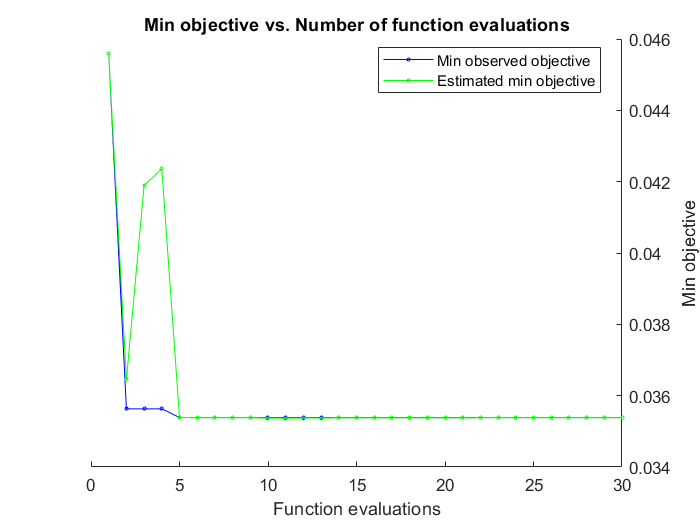

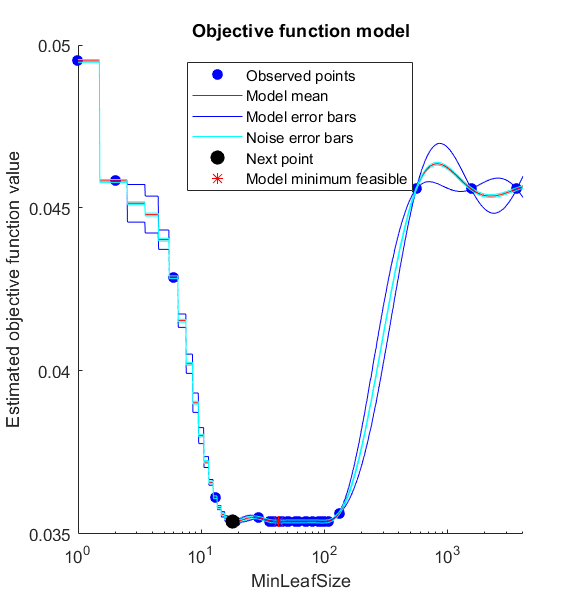


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 46.9297 seconds.
Total objective function evaluation time: 5.7361

Best observed feasible point:
    MinLeafSize
    ___________

        107    

Observed objective function value = 0.035385
Estimated objective function value = 0.035395
Function evaluation time = 0.18069

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        96     

Estimated objective function value = 0.035381
Estimated function evaluation time = 0.18785



Mdl =   ClassificationTree
                       PredictorNames: {'RANDID'  'SEX'  'TOTCHOL'  'AGE'  'SYSBP'  'DIABP'  'CURSMOKE'  'CIGPDAY'  'BMI'  'BPMEDS'  'HEARTRTE'  'GLUCOSE'  'educ'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 8139
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


% Automatically find the best hyperparameters using CV
Mdl = fitctree(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto')

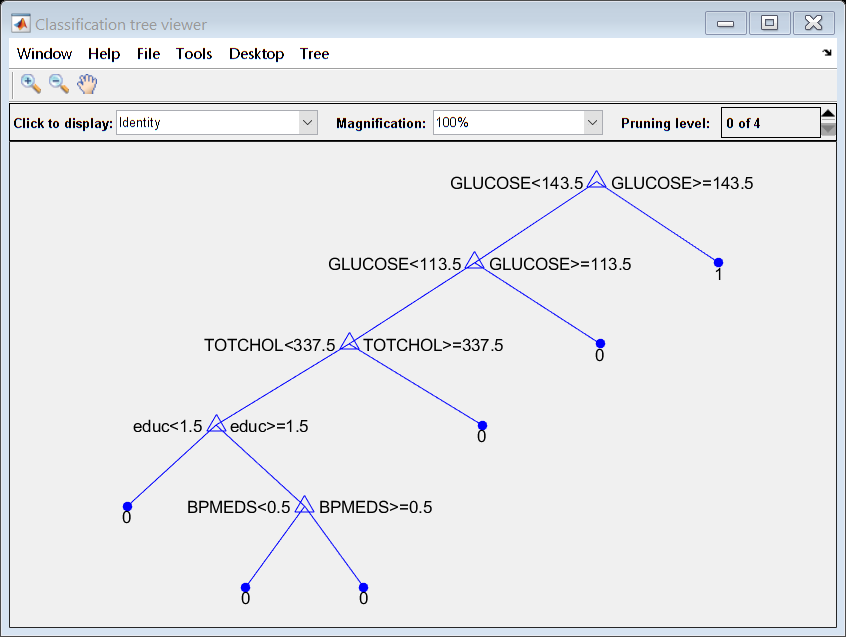

view(Mdl, 'mode', 'graph')

Note 1: click on leaves to see statistics for each category in the viewer.

Note 2: the decision tree can also output probabilities for the groups.

### Assessing DT model performance (classification)

For any predictive model, we always want to know how well it performs with unseen data. The metric we use to evaluate performance depends on what type of decision tree we built. For classification-based DT models, we can use: 

- **Accuracy**: the proportion of observations that were correctly classified

- **Precision**: the proportion of observations for a class that were actually correct

- **Recall**: the proportion of observations for a class that were correctly classified

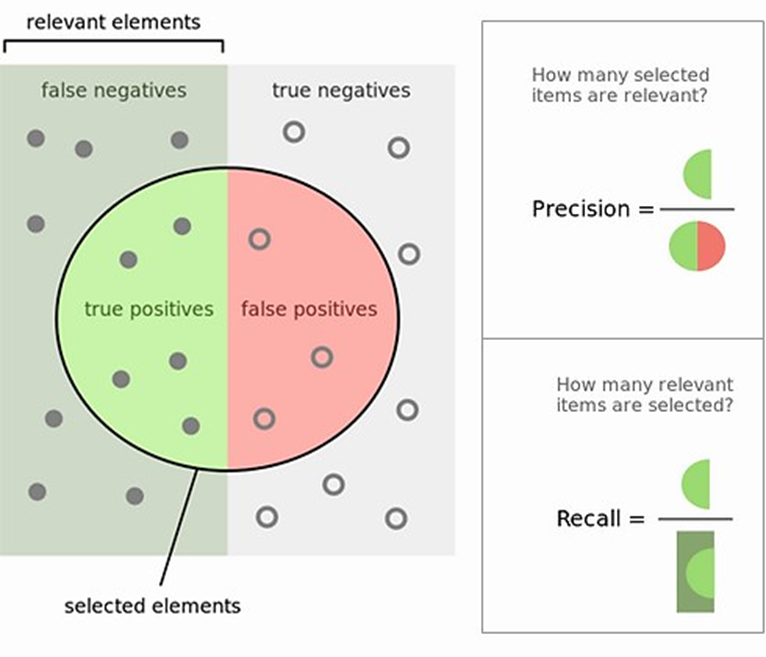

We can evaluate this information manually: 

% Determine predictions for test set
Ypred = predict(Mdl, Xtest);

% Assess overall accuracy and precision + recall for predicting diabetes
accuracy = mean(Ypred == Ytest)

accuracy = 0.9662

tp = sum(Ypred == 1 & Ytest == 1); 
fp = sum(Ypred == 1 & Ytest == 0); 
fn = sum(Ypred == 0 & Ytest == 1); 
precision = tp / (tp + fp)

precision = 0.8254

recall = tp / (tp + fn)

recall = 0.3270

Or we can use the built-in function `confusionchart` to visually interpret our classified performance: 

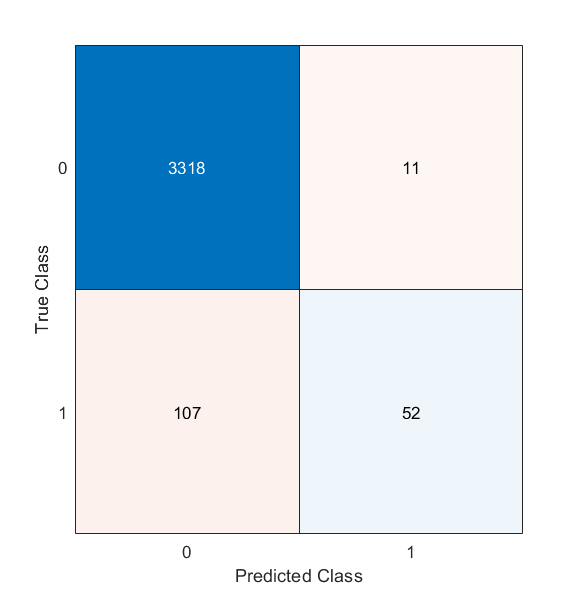

% Visualize confusion chart
confusionchart(Ytest, Ypred)

## Regression-based DT

For regression-based models, we can assess the **correlation** between model predictions and the actual output values. Regression-based decision trees can be built using the `fitrtree` function in MATLAB. The code below builds a regression-based DT model for predicting age based on patient data from the Framingham dataset: 

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      4.3625 |     0.33387 |      4.3625 |      4.3625 |           11 |


|    2 | Best   |      4.2409 |     0.11362 |      4.2409 |      4.2532 |          164 |


|    3 | Accept |      4.4063 |    0.081633 |      4.2409 |      4.2559 |         2743 |


|    4 | Accept |      4.6003 |     0.65489 |      4.2409 |      4.2451 |            2 |


|    5 | Accept |      4.2414 |     0.11604 |      4.2409 |      4.2407 |          180 |


|    6 | Best   |       4.228 |     0.11434 |       4.228 |      4.2282 |           75 |


|    7 | Best   |      4.2278 |     0.11551 |      4.2278 |       4.228 |           85 |


|    8 | Best   |       4.227 |      0.1117 |       4.227 |      4.2276 |           78 |


|    9 | Best   |      4.2253 |     0.12183 |      4.2253 |      4.2268 |           70 |


|   10 | Accept |      4.2284 |     0.13375 |      4.2253 |      4.2268 |           58 |


|   11 | Accept |      4.3233 |     0.10092 |      4.2253 |      4.2268 |          840 |


|   12 | Accept |      4.2896 |     0.09838 |      4.2253 |      4.2269 |          363 |


|   13 | Best   |      4.2246 |     0.11545 |      4.2246 |      4.2264 |           71 |


|   14 | Accept |      4.5297 |    0.078614 |      4.2246 |      4.2259 |         4068 |


|   15 | Accept |      4.2499 |     0.13366 |      4.2246 |       4.226 |           32 |


|   16 | Accept |      4.2259 |     0.11827 |      4.2246 |      4.2259 |           68 |


|   17 | Accept |      4.3772 |     0.11458 |      4.2246 |      4.2258 |         1481 |


|   18 | Accept |      4.6392 |     0.85132 |      4.2246 |      4.2259 |            1 |


|   19 | Accept |      4.2345 |     0.11264 |      4.2246 |      4.2262 |          115 |


|   20 | Accept |      4.2748 |     0.15429 |      4.2246 |      4.2262 |           21 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |      4.2334 |      0.1306 |      4.2246 |      4.2264 |           47 |


|   22 | Accept |      4.2667 |     0.10184 |      4.2246 |      4.2258 |          241 |


|   23 | Accept |      4.2259 |     0.11943 |      4.2246 |      4.2259 |           68 |


|   24 | Accept |      4.3132 |    0.092375 |      4.2246 |      4.2258 |          557 |


|   25 | Accept |      4.5358 |     0.47357 |      4.2246 |      4.2258 |            5 |


|   26 | Accept |      4.3046 |       0.173 |      4.2246 |      4.2258 |           16 |


|   27 | Accept |      4.4011 |    0.077442 |      4.2246 |      4.2258 |         2027 |


|   28 | Accept |      4.2259 |     0.17267 |      4.2246 |      4.2258 |           68 |


|   29 | Accept |      4.3597 |    0.090201 |      4.2246 |      4.2258 |         1093 |


|   30 | Accept |      4.2256 |     0.12674 |      4.2246 |      4.2257 |           67 |


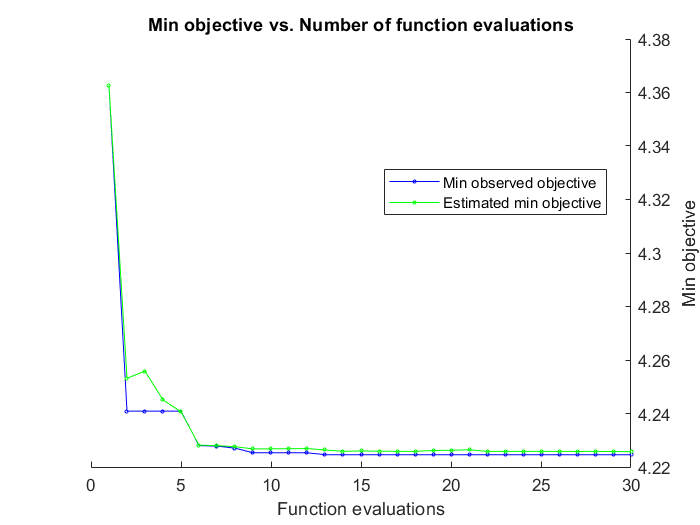

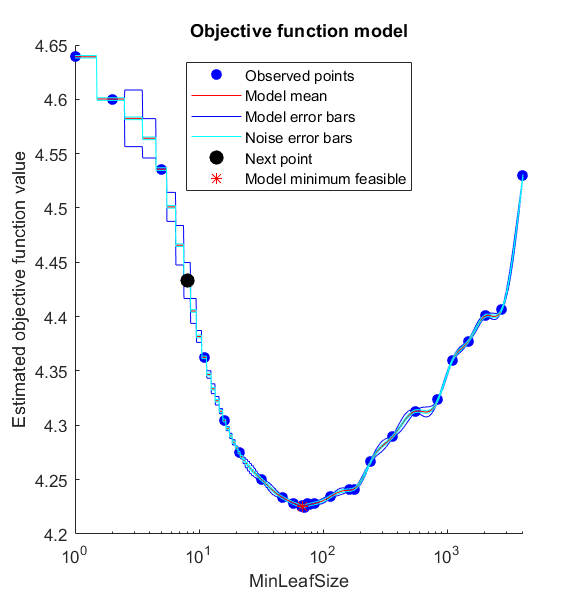


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 46.0248 seconds.
Total objective function evaluation time: 5.3332

Best observed feasible point:
    MinLeafSize
    ___________

        71     

Observed objective function value = 4.2246
Estimated objective function value = 4.2259
Function evaluation time = 0.11545

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        68     

Estimated objective function value = 4.2257
Estimated function evaluation time = 0.12277



% Define input/output and training/testing sets
[X, Y] = deal(fram(:, [1:3 5:11]), fram.AGE); 
idx = crossvalind('HoldOut', numel(Y), 0.3); 
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

% Build regression model with automated hyperparameter optimization
regTree = fitrtree(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto'); 

% Predict outcome for test set
Ypred = predict(regTree, Xtest);

% Assess correlation between actual vs. predicted outcomes
[r, p] = corr(Ytest, Ypred); 
fprintf('R = %4.2f, p = %4.2e \n', r, p)

R = 0.53, p = 1.67e-250 


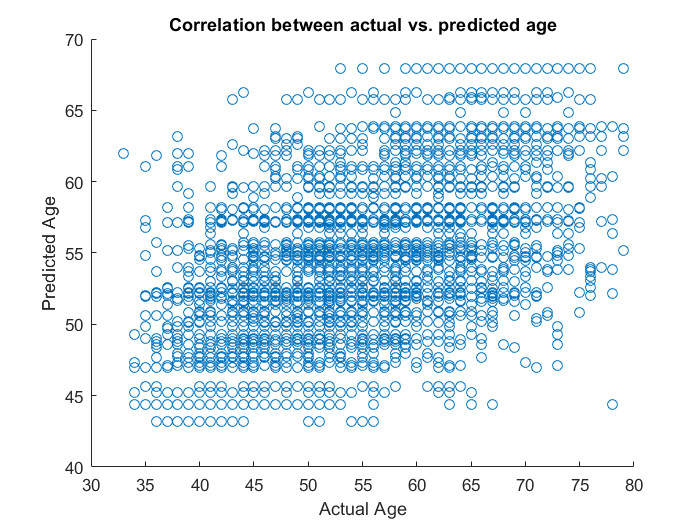

% Visualize scatter plot of actual vs. predicted outcomes
figure
scatter(Ytest, Ypred)
xlabel('Actual Age')
ylabel('Predicted Age')
title('Correlation between actual vs. predicted age')

## Summary

- A decision tree is a non-linear predictive model that can be used for both classification and regression tasks

- Decision trees are a **white-box** model, meaning that they are interpretable and explainable

- The structure of a decision tree is defined by rule-based nodes connected by edges

- The best decision tree attributes are determined by optimizing class separation (e.g. minimizing entropy)

- Hyperparameter tuning is needed to develop an optimal model that is generalizable to new data

- A deep tree tends to overfit to the training data; we can avoid this by defining hyperparameters that yield a shallow tree instead

### Built-in MATLAB functions introduced in this lesson:

- `fitctree`:      develops a classification-based decision tree

- `view`:              used to view the structure of the decision tree

- `resubLoss`:    calculates the resubstitution loss

- `cvloss`:          calculates the cross-validation loss

- `prune`:            prunes a tree given a specified level

- `kfoldloss`:    calculates the training error for a tree built using cross-validation

- `predict`:        generates predictions given a trained model and input (feature) data

- `fitrtree`:      develops a regression-based decision tree